# Part 2: Image Restore

% read the image
degraded_a = imread('Degraded_A.tif');
degraded_d = imread('Degraded_D..tif');
runway = imread('runway-1.tif');
spine = imread('spine.tif');

**Image quality comments:**

- degraded_a has noise -> dilate? disk size 2 but dilate also reduce the image quality so have to do something to restore the initial image sharpness/quality

- degraded_d is very blurry -> imsharpen()? 

- runway has no shadow or dark area -> can plot histogram to precisely show the shade range of this image -> probably perform intensity remapping by applying new T1 and T2 value?

- spine has distinguished shadow and bright areas, the shade range should somewhat be the same so that fine details are kept. the bright area is too bright and the dark is too dark -> histogram equalization and test how it goes

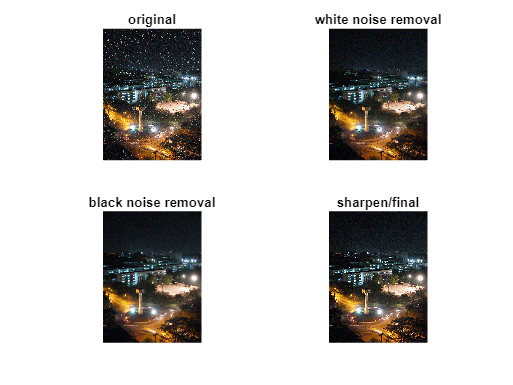

% degraded_a image restoration
a_filter = strel('disk', 1);
a = imopen(degraded_a, a_filter);
a2 = imclose(a, a_filter);
sharpen_a = imsharpen(a2, "Radius", 2, "Amount", 1);
% plot images for comparison
figure;
subplot(221); imshow(degraded_a); title('original');
subplot(222); imshow(a); title('white noise removal');
subplot(223); imshow(a2); title('black noise removal');
subplot(224); imshow(sharpen_a); title('sharpen/final');

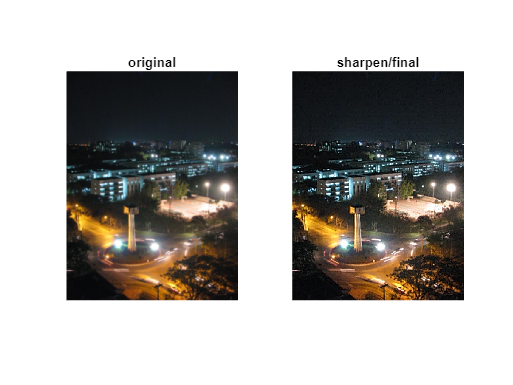

% degraded_d image restoration
sharpen_d = imsharpen(degraded_d, "Radius", 1, "Amount", 6.5);
% plot
figure;
subplot(121); imshow(degraded_d); title('original');
subplot(122); imshow(sharpen_d); title('sharpen/final');

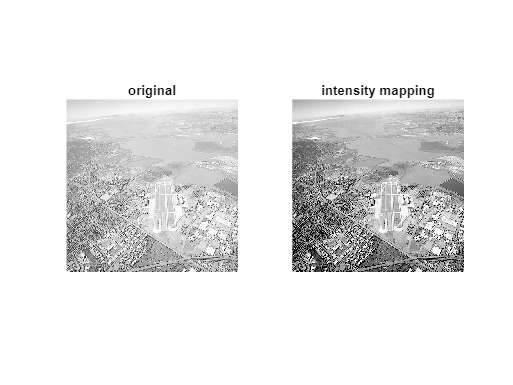

% runway
% initialise new value for image
T1 = 100;
T2 = 255;
% apply new range to current image
rw_ad = imadjust(runway, [T1/255 T2/255], [0 1]);
% plot the images
figure;
subplot(121); imshow(runway); title('original');
subplot(122); imshow(rw_ad); title('intensity mapping');

**comment:** after intensity remapping, the range is better but the concentration of pixels is still a bit skewed. try to fix with histogram equalization after this. compare original, intensity mapping only, and histogram equalization only. (i have tried combining mapping and equalizing (A) but the result of (A) and equalization only appear identical in terms of range, pixel distribution, and final image outcomes). 

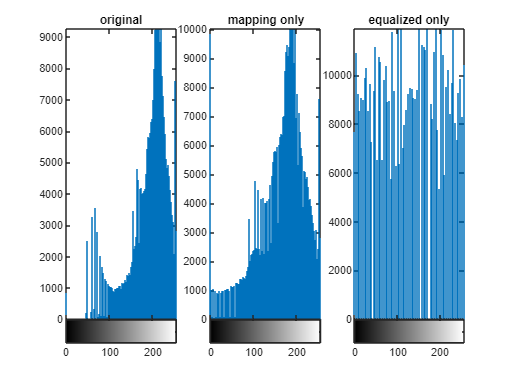

% histogram equal from the start
runway_hist1 = histeq(runway);
% plot histograms
figure;
subplot(131); imhist(runway); title('original');
subplot(132); imhist(rw_ad); title('mapping only');
subplot(133); imhist(runway_hist1); title('equalized only');

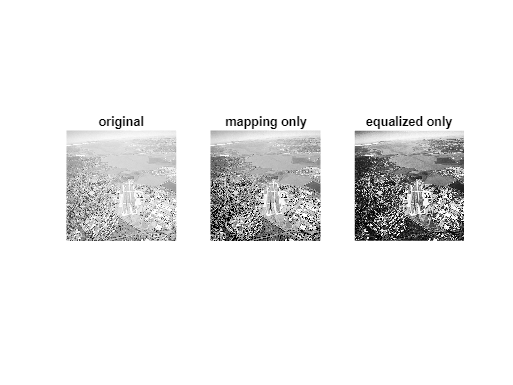

% plot images
figure;
subplot(131); imshow(runway); title('original');
subplot(132); imshow(rw_ad); title('mapping only');
subplot(133); imshow(runway_hist1); title('equalized only');

% spine restoration

**comment: **majority of the pixel is concentrated at the darker end of the spectrum. perform histogram equalization? maybe gamma correction (pretty alright result imo but gives the same effect as the histogram equalization but you can customize the gamma value -> easier to tweak around and obtain more information from the image according to users' needs. 

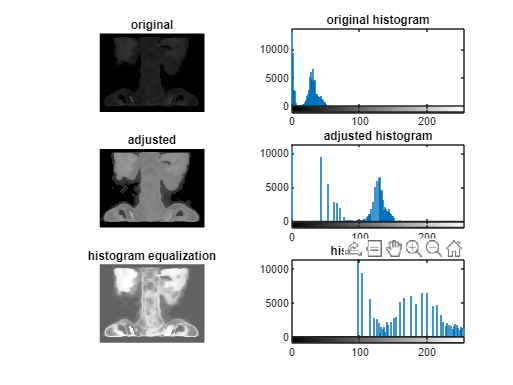

spine = imread('spine.tif');
X = 128;
% apply changes to the original image
spine_ad = imadjust(spine, [], [], 0.32);
spine_he = histeq(spine, X);
spine_final = imadjust(spine_he, [95/255 255/255], [0 1]);
% plot images and their corresponding histograms
figure;
subplot(321); imshow(spine); title('original');
subplot(322); imhist(spine); title('original histogram');
subplot(323); imshow(spine_ad); title('adjusted');
subplot(324); imhist(spine_ad); title('adjusted histogram');
subplot(325); imshow(spine_he); title('histogram equalization');
subplot(326); imhist(spine_he); title('histeq histogram');

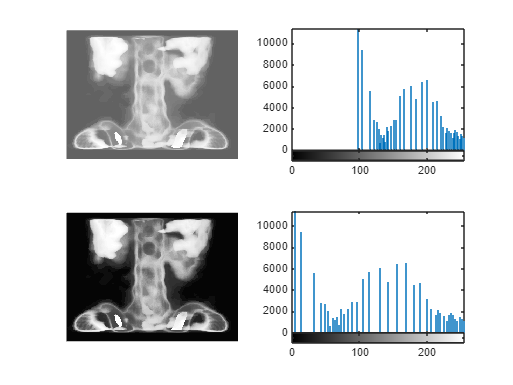


figure;
subplot(221); imshow(spine_he);
subplot(222); imhist(spine_he);
subplot(223); imshow(spine_final);
subplot(224); imhist(spine_final);